# **    FEM2D: Thermal convetion problems using Triangular Elements**

Consider the thermal Boundary value problem,

                                       
$$
-\frac{\partial^{2} T}{\partial x^{2}}- \frac{\partial^{2} T}{\partial y^{2}} = 0,\quad (x,y)\in \Omega = [-1,1]^{2}\setminus B^{2}_{1/2}(0,0),
$$


with boundary conditions:

    
$$\bullet\ T(x,-1) = 50^{\circ}\text{C},\ x\in[-1,1],\\
\bullet\ T(x,y) = 15^{\circ}\text{C}, \ (x,y) \in\partial B^{2}_ {1/2}(0,0),\\
\bullet\ \frac{\partial T}{\partial x}(-1,y) = \frac{\partial T}{\partial x}(1,y) = 0,\ y\in [-1,1],\\
\bullet\ \text{and convection on the top boundary ($y=1, x\in[-1,1]$)\, with $\beta = 2$\, and $T_{\infty}=-5^{\circ}$C.} $$


Use the FEM with the mesh given in `the` file `CircleHolemesh01.m` to find the temperature distribution on $\Omega$.

clearvars
close all

a11 = 1.0;
a12 = 0.0;
a21 = a12;
a22 = a11;
a00 = 0.0;
f   = 0.0;

tempCirc = 15.0;
tempBot = 50.0;
beta = 2;
Tinf = -5;

p=[0.5, 0.2];

eval('CircleHolemesh01')

numNod = size(nodes,1);
numElem = size(elem,1);

numbering = 0;
plotElementsOld(nodes, elem, numbering);
hold on


Let's pick the nodes at the top, at the bottom and at the circle

nodesTop = find(nodes(:,2) > 0.99);
nodesBot = find(nodes(:,2) < -0.99);
nodesCirc = find(sqrt(nodes(:,1).^2 + nodes(:,2).^2)< 0.501);

And plot the selected nodes...

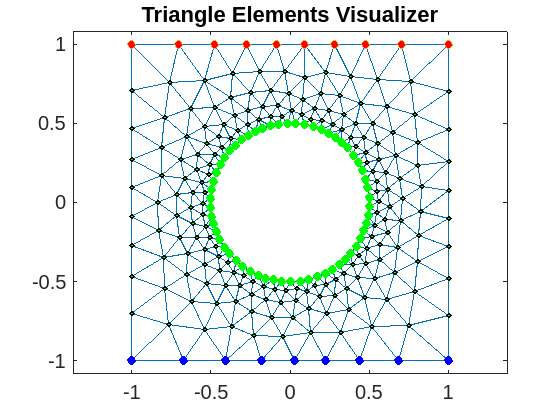

plot(nodes(nodesTop,1),nodes(nodesTop,2),'o','markerFaceColor','red')
plot(nodes(nodesBot,1),nodes(nodesBot,2),'o','markerFaceColor','blue','Color','blue')
plot(nodes(nodesCirc,1),nodes(nodesCirc,2),'o','markerFaceColor','green','Color','green')
hold off

coeff=[a11,a12,a21,a22,a00,f];
K = zeros(numNod);
F = zeros(numNod,1);
Q = zeros(numNod,1);

for e=1:numElem
    [Ke, Fe] = linearTriangElement(coeff,nodes,elem,e);
    rows =[elem(e,1),elem(e,2),elem(e,3)];
    cols = rows;
    K(rows,cols) = K(rows,cols) + Ke;
    if coeff(6) ~= 0
        F(rows) = F(rows) + Fe;
    end
end
Kini = K; %save a copy of the stifness matrix for the post porcess

**Boundary conditions**

fixedNodes = [nodesBot',nodesCirc'];
freeNodes = setdiff(1:numNod,fixedNodes);

Natural B.C.: in this example, due to convetion on the top boundary

convNodes = nodesTop';
[K,Q] = applyConvTriang(convNodes,beta,Tinf,K,Q,nodes,elem);

Essential B.C.

u = zeros(numNod,1);
u(nodesBot) = tempBot;
u(nodesCirc) = tempCirc;

Reduced system

Im = F(freeNodes) + Q(freeNodes) - K(freeNodes,fixedNodes)*u(fixedNodes);
Km = K(freeNodes,freeNodes);

Solve the reduced system

um = Km\Im;
u(freeNodes) = um;

Post process: computation of $$Q$$'s, tabular and plot.

Q = Kini*u-F;

table.Nod = (1:numNod)';
table.X = nodes(:,1);
table.Y = nodes(:,2);
table.U = u;
table.Q = Q;

format short e
struct2table(table)

ans = 260×5 table
       Nod             X              Y             U              Q     
    __________    ___________    ___________    __________    ___________

    1.0000e+00    -1.0000e+00    -1.0000e+00    5.0000e+01     6.9893e+00
    2.0000e+00    -1.0000e+00     1.0000e+00    3.2131e+00    -2.4448e+00
    3.0000e+00     1.0000e+00    -1.0000e+00    5.0000e+01     6.7723e+00
    4.0000e+00     1.0000e+00     1.0000e+00    3.2151e+00    -2.4281e+00
    5.0000e+00    -1.0000e+00    -4.6643e-01    2.9081e+01    -7.0311e-15
    6.0000e+00    -1.0000e+00    -2.7277e-01    2.3482e+01     4.3029e-15
    7.0000e+00    -1.0000e+00    -8.7995e-02    1.9437e+01    -5.2903e-15
    8.0000e+00    -1.0000e+00     9.1708e-02    1.6461e+01     7.9632e-15
    9.0000e+00    -1.0000e+00     2.6827e-01    1.4016e+01     2.6443e-

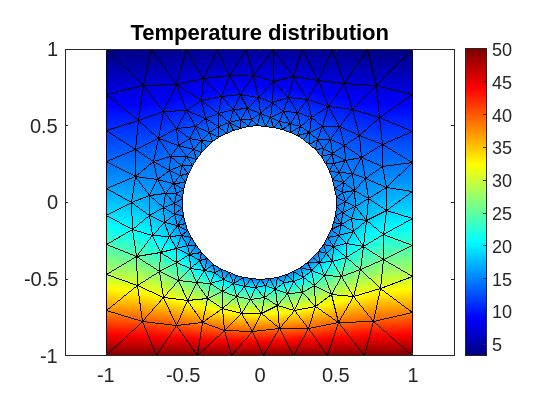


title='Temperature distribution';
colorMap = 'jet';
plotContourSolution(nodes,elem,u,title,colorMap)

## Exercise 1:

Compute the temperature for the point **p=[0.5, 0.2]**.

for e = 1:numElem
    v1 = nodes(elem(e,1),:);
    v2 = nodes(elem(e,2),:);
    v3 = nodes(elem(e,3),:);
    vertexs = [v1;v2;v3];
    [alphas, isInside] = baryCoord(vertexs, p);
    if isInside > 0
        numElemP = e;
        numNodsP = elem(numElemP,:);
        interpTempAtP = alphas * u(numNodsP);
        break;
    end
end

fmt = ['\nInterpolated temp.\n', ...
       'Point p = (%.2f,%.2f)\n',...   
       'Element Num: %4d\n',...
       'Nodes: %d, %d, %d\n', ...
       'Temp.: %12.5e%cC\n'
      ];
fprintf(fmt,p,numElemP,numNodsP,interpTempAtP,char(0176))


Interpolated temp.
Point p = (0.50,0.20)
Element Num:  219
Nodes: 217, 199, 210
Temp.:  1.48459e+01°C
